Object Extraction Code

pathx = 'Images/Misc_Components';
imgdir = dir(pathx);

pathcsv = readtable('Images/Misc_Components-export.csv');

xt = 1;
for i = 1:length(pathcsv.filename)
        imgname = pathcsv.filename{i}
        img = imread([pathx,'/',imgname]);
        x = round(pathcsv.xmin(i));
        y = round(pathcsv.ymin(i));
        width = round(pathcsv.xmax(i));
        height = round(pathcsv.ymax(i));
        vc = [x,y,width,height];
        jx = sum(vc);
        jt = find(vc == 0);
        vc(jt) = 1;
        if jx ~= 0 
            img_cut = img(vc(2):vc(4),vc(1):vc(3),1:3); % Img Cutted or extrated from bounding box
            imshow(img_cut)
            imwrite(img_cut, ['MISC/',num2str(xt),'_',imgname]);
            imgc{xt} = imgname;
            labelx{xt} = pathcsv.label{i};
            xt = xt +1;
            close gcf
            clear img img_cut jt
        end
        
end

writetable(ans,'misc_labels.csv')

for i = 3:length(t.name)
    jf = strsplit(t.name{i},'_');
    j(i-2) = str2num(jf{1});
end

[~,jind] = sort(j);

pathx = 'Images/Train';
imgdir = dir(pathx);

csv1 = csvx('Data/Train.csv');

xy = unique(csv1.label)

xy = 4×1 cell array
    {'Insulator'  }
    {'Light'      }
    {'Pole'       }
    {'Transformer'}


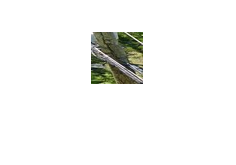

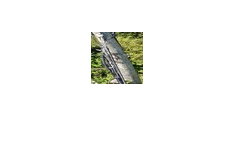


for i = 1:length(xy)
    x = strfind(csv1.label,xy{i});
    tf = ~cellfun(@isempty,x);
    jx = csv1.filename(tf);
        for j = 1:length(jx)
            d=[pathx,'/',jx{j}];
            ximg = imread(d);
            imshow(ximg)
            imwrite(ximg, ['IMAGES/Train/',xy{i},'/',jx{j}]);
            close gcf
        end
    clear tf x jx
end